# **Task_00:**  The Model Parameters

**Objective:**

- This MATLAB script defines parameters that can be used for modeling a 1-DOF robotic manipulator.

 The system that we're going to explore is shown below:

`Bradley Horton : 18-Nov-2026, bhorton@mathworks.com`

# Instructions:

Run and then review this script.

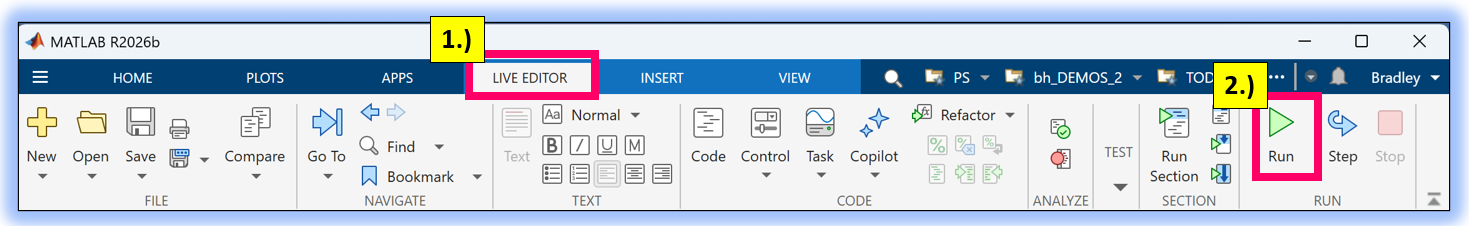

# Clear the workspace

clear

# Our ENVIRONMENT

Define gravity to be in the negative Z direction of our Inertial reference frame

gravity_vec = [0,0,-9.8065]; % (m/s^2)

# The Robot Arm:

Define the geometry and inertial properties of our robot arm (aka the LINK)

- see the data container definition and UNITS, here - [`bh_brick_CLS.m`](matlab:  open bh_brick_cls.m)

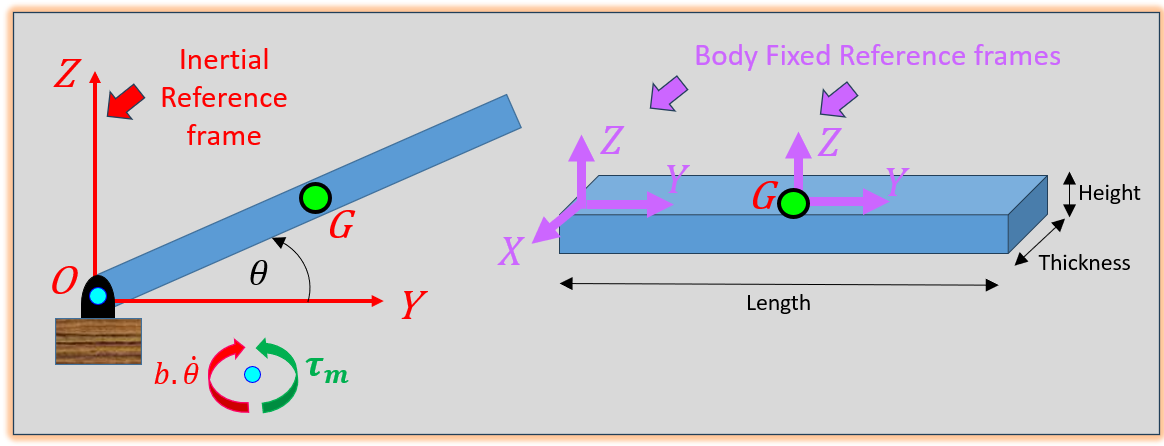

my_LINK_OBJ = bh_brick_CLS();

We'll use the default property values defined in [`bh_brick_CLS.m`](matlab:  open bh_brick_cls.m) , but you can overwrite these using the standard DOT notation

OK, so what have we got ?

display( my_LINK_OBJ )

my_LINK_OBJ =   bh_brick_CLS with properties:

           Length: 0.3000
           Height: 0.0500
        Thickness: 0.0100
             Mass: 0.1875
    LHT_body_axes: "YZX"
          vec_XYZ: [0.0100 0.3000 0.0500]


# The Joint:

Define properties associated with the joint that we'll connect to the robot arm:

- see the data container definition and UNITS, here - [`bh_joint_CLS.m`](matlab:  open bh_joint_CLS.m)

### Define some damping at the joint:

We will assume that the rotational joint experiences viscous damping. The damping torque is a function of the relative joint velocity,  e.g.:  $\tau_{\mathrm{DAMP}} =b_1 \ldotp \dot{\theta}$

my_joint_1_OBJ         = bh_joint_CLS();

### The System pose and INITIAL Conditions:

Here are the system INITIAL conditions

- 
$$\theta \left(t_0 \right)=0\;\;\;\;\left(\mathrm{rad}\right)$$


- 
$$\dot{\theta} \left(t_0 \right)=0\;\;\;\;\left(\frac{\mathrm{rad}}{\sec }\right)$$


my_joint_1_OBJ.theta     =  0*pi/180; % (rad)
my_joint_1_OBJ.theta_dot =  0*pi/180; % (rad/sec) 

OK, so what have we got ?

display( my_joint_1_OBJ )

my_joint_1_OBJ =   bh_joint_CLS with properties:

        theta: 0
    theta_dot: 0
         Damp: 1.0000e-03


# The DC motor:

Define the electrical AND mechanical properties of the DC Motor that will drive the robot

- see the data container definition and UNITS, here - [`bh_DC_motor_CLS.m`](matlab:  open bh_DC_motor_CLS.m)

my_DC_moto_OBJ = bh_DC_motor_CLS();

OK, so what have we got ?

display( my_DC_moto_OBJ )

my_DC_moto_OBJ =   bh_DC_motor_CLS with properties:

         arm_R: 1.5000
         arm_L: 3.1000e-05
           K_t: 0.0537
       rotor_I: 1.2900e-04
    rotor_damp: 1.0000e-06
         V_max: 24


# The DC motor:

my_DC_moto_OBJ = bh_DC_motor_CLS();

# The Gearbox:

Define the Gear ratio for the gearbox that we attach the DC motor to

- see the data container definition and UNITS, here - [`bh_Gearbox_CLS.m`](matlab:  open bh_Gearbox_CLS.m)

Recall the definition of the gear ratio:

- 
$$N\;\;=\;\frac{{\omega \;}_{\mathrm{INPUT}} }{\omega_{\;\mathrm{OUTPUT}} }\;\;=\;\frac{\tau_{\;\mathrm{OUTPUT}} }{\tau_{\;\mathrm{INPUT}} }$$


my_gbox_OBJ = bh_Gearbox_CLS();

OK, so what have we got ?

display( my_gbox_OBJ )

my_gbox_OBJ =   bh_Gearbox_CLS with properties:

    N_gear: 10


# The H-Bridge:

We'll insert a H-bridge between our voltage source and the DC motor. 

- see the data container definition and UNITS, here - [`bh_HBridge_CLS.m`](matlab:  open bh_HBridge_CLS.m)

my_HBridge_OBJ = bh_HBridge_CLS(my_DC_moto_OBJ.V_max);

display( my_HBridge_OBJ )

my_HBridge_OBJ =   bh_HBridge_CLS with properties:

      V_max: 24
          R: 1.0000e-03
    R_diode: 5.0000e-04


# Next Steps:

You're now ready for Task_01

- [`TASK_01_create_mechanical_arm.mlx`](matlab:  open  TASK_01_create_mechanical_arm.mlx)

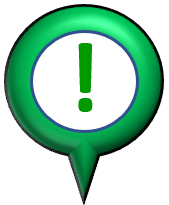 FYI:  If you want to launch the Exercise **START_HERE** file .... click below:

- [`EX_START_HERE_PLEASE.m`](matlab:  open EX_START_HERE_PLEASE.m)